%% Sample Data information
datanz.imagenames = {'02-12-2016_21_20_17_top.fits';...
                     '02-12-2016_21_19_27_top.fits';...
                     '02-12-2016_21_18_37_top.fits' };
datanz.totalimages = length(datanz.imagenames);              
datanz.greenevap = 0.07;
datanz.irevap = 1;
datanz.seqmode = 21;
datanz.roi_rect = [217, 110, 324-217, 330-110];


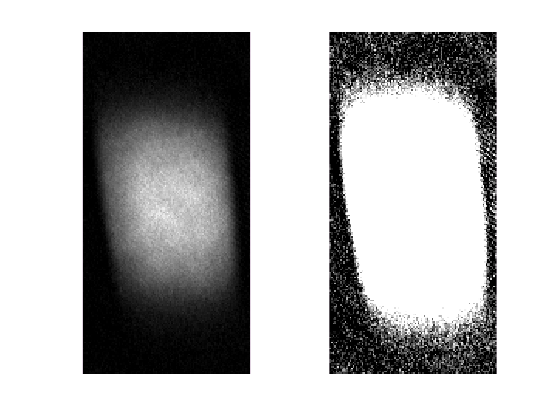

%% Load sample data
if 0 || ~isfield(datanz,'a')
    datapath = 'D:\Dropbox Sync\Dropbox (MIT)\BEC1\Image Data and Cicero Files\Data - Raw Images\2016\2016-02\2016-02-12';
    
    datanz.raw_imdata{1} = load_img2(fullfile(datapath,datanz.imagenames{1}), datanz.roi_rect);
    datanz.averageOD = datanz.raw_imdata{1} / datanz.totalimages;
    
    for imnum = 2:datanz.totalimages
        datanz.raw_imdata{imnum} = load_img2(fullfile(datapath,datanz.imagenames{imnum}), datanz.roi_rect);
        datanz.averageOD = datanz.averageOD + datanz.raw_imdata{imnum} / datanz.totalimages;
    end
    
    figure; ax1 = subplot(1,2,1);
    imshow(datanz.averageOD,[0 1.5]); set(ax1,'YDir','normal');
    ax2 = subplot(1,2,2);
    imshow(datanz.averageOD,[0 0.1]); set(ax2,'YDir','normal');
end

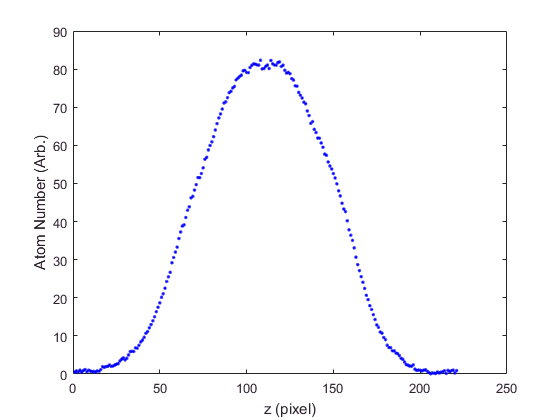

%% Integrated profiles and TF fits
datanz.N_z = sum(datanz.averageOD,2);
datanz.z = (1:size(datanz.N_z,1))';
figure; plot(datanz.z, datanz.N_z,'b.'); xlabel('z (pixel)'); ylabel('Atom Number (Arb.)');

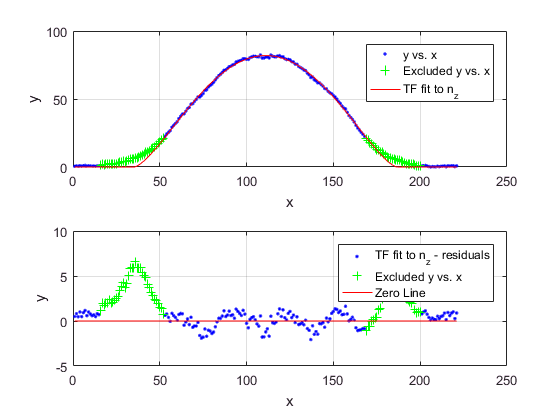

% Fitting variables
x = datanz.z; y = datanz.N_z;
fitres = createFitTFnz(x,y);